%% clear cache
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d_8k.wav";
output_file_path = "C:/Users/sekijima/Desktop/演習/DataSet/LinearPredictiveCoding/synthesized_signal_by_LPCVocoder_8k.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path, output_file_path)

audio_file_manipulator =   AudioFileManipulator のプロパティ:

     input_file_path: "vaiueo2d_8k.wav"
    output_file_path: "C:/Users/sekijima/Desktop/演習/DataSet/LinearPredictiveCoding/synthesized_signal_by_LPCVocoder_8k.wav"
              signal: []
         sample_rate: []
         information: []


audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d_8k.wav
output_file_path : C:/Users/sekijima/Desktop/演習/DataSet/LinearPredictiveCoding/synthesized_signal_by_LPCVocoder_8k.wav
signal shape : (6348, 1)
sample_rate: 8000 [Hz]
             Filename: 'C:\Users\sekijima\Desktop\演習\DataSet\LinearPredictiveCoding\vaiueo2d_8k.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8000
         TotalSamples: 6348
             Duration: 0.7935
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



%% set LinearPredictiveCoding class parameters
start_point = 1362;  % あのスタート位置
continue_time = 32; % [ms]
continue_point = int32(continue_time * audio_file_manipulator.information.SampleRate / 1000);

%% generate LPCVocoder instance
lpc_vocoder = LinearPredictiveCodingVocoder(audio_file_manipulator.signal(start_point : start_point + continue_point - 1), audio_file_manipulator.information.SampleRate);
lpc_vocoder.display_properties();

----------------------------------------------
----------------- LPC Vocoder ----------------
signal size : (256, 1)
window_mode : hamming
order : 30
threshold : 0.000100
internal_status size : (30, 1)
synthesized_signal size : (256, 1)
impulse_response size : (256, 1)
----------------------------------------------



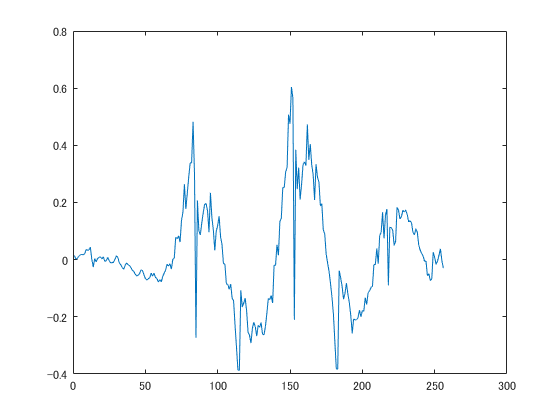

plot(lpc_vocoder.synthesized_signal);

soundsc(lpc_vocoder.synthesized_signal, audio_file_manipulator.information.SampleRate);
audio_file_manipulator.signal = lpc_vocoder.synthesized_signal;
audio_file_manipulator.normalize();
audio_file_manipulator.change_scale();
audio_file_manipulator.save_properties();